# **Week L6: Single-Carrier with Alamouti Coding**

This script implements a simplified optic fibre communications system using Alamouti coding

## **Transmitter**

The model of the transmitter consists of the following elements:

- A symbol generator which modulates source bits using QPSK

- A pulse shaper which creates an electrical signal using the generated symbols

- An IQ modulator which modulates the output of a laser ac cording to an electrical signal

### Alamouti Coding

clearvars

% Parameters
NSymb = 300000; % No. of symbols 
SpS = 2; % Samples per symbol
Rs = 50e9; % Symbol rate in symbols/sec
T = 1/(SpS*Rs); % Sampling period in s
t= [0:1:NSymb*SpS - 1]*T; % Time vector for plotting time-series data

voltageLevelsQPSK = [asin(-1/sqrt(2)), asin(1/sqrt(2))]'; % Discrete voltages for QAM
voltageLevelsQAM = [asin(-3/sqrt(10)), asin(-1/sqrt(10)), asin(1/sqrt(10)), asin(3/sqrt(10))]';
DCOffset = 0; % DC offset of modulated current in V

% --------------------------------------------------------------------------------------

% Generating random bit sequence(s)
sourceBitsQPSK = randi([0 1], NSymb*2, 1); % Matrix of source bits for QPSK
sourceIntsQPSK = bit2int(sourceBitsQPSK, 2); % Vector of source bits converted to ints
sourceSymbolsQPSK = pskmod(sourceIntsQPSK, 4, pi/4); % Maps source bit vector to symbol vector
codedSymbolsQPSK = AlamoutiCoding(sourceSymbolsQPSK); % Encodes symbols using Alamouti coding

vI_QPSK = real(codedSymbolsQPSK);
vQ_QPSK = imag(codedSymbolsQPSK);

vI_QPSK_upsampled = repelem(vI_QPSK, SpS, 1); % Upsampling according to SpS
vQ_QPSK_upsampled = repelem(vQ_QPSK, SpS, 1); % Upsampling according to SpS

% Visualising in-phase and quadrature voltage
% stairs(t(1:10*SpS), vI_QPSK_upsampled(1:10*SpS,1), "o-");
% hold on
% stairs(t(1:10*SpS), vQ_QPSK_upsampled(1:10*SpS,1), "o-");
% title("Modulated Voltage for QPSK")
% xlabel("Time / s")
% ylabel("Voltage / V")
% legend("In-phase", "Quadrature")
% grid on
% hold off

### Pulse Shaping

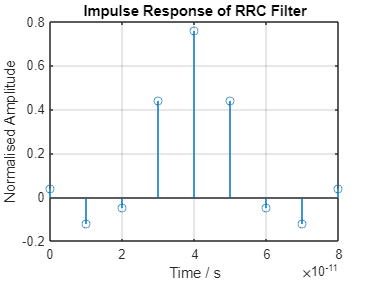

% RRC filter parameters
filterSpan = 4; % Span of RRC filter in no. of symbols
rollOff = 0.25;
filterResponse = rcosdesign(rollOff, filterSpan, SpS)';
samples = 1+(NSymb-1)*SpS + filterSpan*SpS;
v_shaped_t = [0:1:samples-1]*T;

% Visualisation of RRC filter
filterResponse_t = [0:1:filterSpan*SpS]*T; % time vector for the filter response
% filterResponse_t_interp = [0:0.25:filterSpan*SpS]*T;
% filterResponse_interp = interp1(filterResponse_t, filterResponse, filterResponse_t_interp, "spline");
% plot(filterResponse_t, filterResponse, "o", filterResponse_t_interp, filterResponse_interp, ":.");

stem(filterResponse_t, filterResponse, '-o');
title('Impulse Response of RRC Filter');
xlabel('Time / s');
ylabel('Normalised Amplitude');
grid on

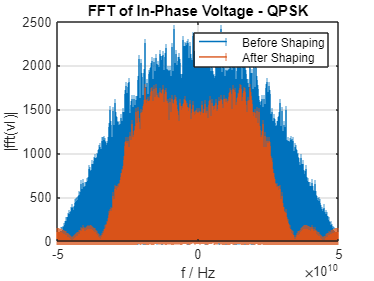


% ---------------------------------------------------------------------------

% Using RRC filter to shape vI and vQ
vI_QPSK_shaped = upfirdn(vI_QPSK, filterResponse, SpS, 1); vQ_QPSK_shaped = upfirdn(vQ_QPSK, filterResponse, SpS, 1);

% Frequency spectrum of voltage waveforms before filtering
fft_vI_QPSK = fftshift(fft(vI_QPSK_upsampled(:,1))); % FFT of noisy signal before shaping
freqArr = [-NSymb*SpS/2:NSymb*SpS/2 - 1]/(T*NSymb*SpS);

fft_vI_QPSK_shaped = fftshift(fft(vI_QPSK_shaped(:,1))); % FFT of nosiy signal after shaping
freqArr_shaped = [-samples/2:samples/2 - 1]/(T*samples);

stem(freqArr, abs(fft_vI_QPSK), "|");
hold on
stem(freqArr_shaped, abs(fft_vI_QPSK_shaped), "|");
title("FFT of In-Phase Voltage - QPSK");
xlabel("f / Hz");
ylabel("|fft(vI)|");
legend("Before Shaping", "After Shaping");
hold off
grid on


% Visualising pulse-shaped voltages
% stairs(v_shaped_t(1:10*SpS + filterSpan), vI_QPSK_upsampled(1:10*SpS + filterSpan,1), "o-");
% hold on
% plot(v_shaped_t(1:10*SpS + filterSpan), vI_QPSK_shaped(1:10*SpS + filterSpan,1), "o-");
% title("Shaped In-Phase Voltage - QPSK");
% ylabel("Voltage / V");
% xlabel('Time / s');
% legend("Before shaping", "After shaping");
% grid on
% hold off

bandwidth = 0.5*(1+rollOff)/T

bandwidth = 6.2500e+10

### IQ Modulation

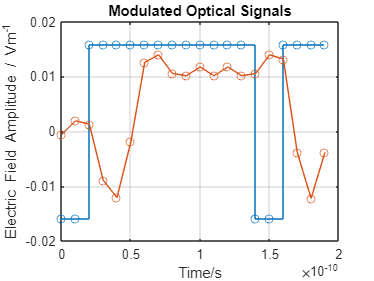

% Initialising laser parameters
lineWidth = 0;
laserPw_dBm = 0;
laserPw_Lin = 1e-3*10^(laserPw_dBm/10);

% Generating output from laser modelled as a continuous-wave source
laserE = Laser(laserPw_dBm, lineWidth, SpS, Rs, NSymb, 2); % Laser output to be used with unshaped signals
laserE_shaped = Laser(laserPw_dBm, lineWidth, SpS, Rs, samples/SpS, 2); % Laser output to be used with shaped signals

% Visualising output from laser
% plot(t(1:20), real(laserE(1:20)), "o-");
% title("Laser Output as a Continous Wave");
% xlabel("Time/s")
% ylabel("Electric Field Amplitude / Vm^{-1}");
% grid on

% Modulating optical signal using IQM
Vpi = pi/2; % Voltge required to change phase of E-field by pi

% Unshaped Signals
modOpticSigQPSK = (vI_QPSK_upsampled+1i*vQ_QPSK_upsampled).*laserE;
modOpticSigQPSK_shaped = (vI_QPSK_shaped+1i*vQ_QPSK_shaped).*laserE_shaped;

% Visualising modulated optical signals
stairs(t(1:10*SpS), real(modOpticSigQPSK(1:10*SpS,1)), "o-");
hold on
plot(t(1:10*SpS), real(modOpticSigQPSK_shaped(1:10*SpS,1)), "o-");
title("Modulated Optical Signals")
xlabel("Time/s")
ylabel("Electric Field Amplitude / Vm^{-1}")
grid on
hold off

### Controlling Effects

% Setting the required effects:

insertCD = false;

singleRotation = false;
multipleRotations = true;

if (singleRotation && multipleRotations == true)
    error('You can only apply either a single rotation or multiple rotations at a given time')
end

insertAWGN = false;

if insertAWGN && multipleRotations
    error('Insertion of AWGN with multiple polarization rotation angles cannot be performed together')
end

CDcompensate = false;

if CDcompensate && ~insertCD
    error('Cannot compensate for CD if it is not added in the first place')
end


## Optical Channel

### Inserting CD

% Inserting CD
D = 17; % Group velocity dispersion in ps/nm/km
CLambda = 1550e-9; % Central wavelength of optical carrier in m
linkLength = 50e3; % Fibre link length in m

clear channelOutQPSK channelOutQPSK_shaped

if insertCD
    channelOutQPSK = CDInsertion(modOpticSigQPSK, SpS, Rs, D, CLambda, linkLength, 2); 
    channelOutQPSK_shaped = CDInsertion(modOpticSigQPSK_shaped, SpS, Rs, D, CLambda, linkLength, 2); 
else
    channelOutQPSK = modOpticSigQPSK;
    channelOutQPSK_shaped= modOpticSigQPSK_shaped;
end

% Debugging addition of CD through immediate CD compensation

% channelOutQPSK_shaped_filtered = upfirdn(channelOutQPSK_shaped(:,1), filterResponse, 1, SpS);
% channelOutQPSK_shaped_filtered = channelOutQPSK_shaped_filtered(filterSpan+1:end-filterSpan);
% 
% debugCDC = OverlapSaveCDC(channelOutQPSK(:,1),D,linkLength,CLambda,Rs,1,SpS,2^8,50);
% debugCDC_shaped = OverlapSaveCDC(channelOutQPSK_shaped,D,linkLength,CLambda,Rs,1,SpS,2^8,50);
% 
% % Evaluating BER when CDC is applied after filtering
% % debugCDC_shaped_filtered = debugCDC_shaped;
% % debugCDC_shaped_filtered(2:2:end) = -conj(debugCDC_shaped_filtered(2:2:end));
% % 
% % debugCDC_shaped_filtered_Ints = pskdemod(debugCDC_shaped_filtered, 4, pi/4);
% % debugCDC_shaped_filtered_Bits = int2bit(debugCDC_shaped_filtered_Ints, 2);
% % [~, BER_debugCDC_shaped] = biterr(debugCDC_shaped_filtered_Bits, sourceBitsQPSK)
% 
% % Evaluating BER when CDC is applied before filtering
% debugCDC_shaped_filtered = upfirdn(debugCDC_shaped, filterResponse, 1, SpS);
% debugCDC_shaped_filtered = debugCDC_shaped_filtered(filterSpan+1:end-filterSpan);
% debugCDC_shaped_filtered(2:2:end) = -conj(debugCDC_shaped_filtered(2:2:end));
% 
% debugCDC_shaped_filtered_Ints = pskdemod(debugCDC_shaped_filtered, 4, pi/4);
% debugCDC_shaped_filtered_Bits = int2bit(debugCDC_shaped_filtered_Ints, 2);
% [~, BER_debugCDC_shaped] = biterr(debugCDC_shaped_filtered_Bits, sourceBitsQPSK)
% 
% % Visualising symbol distributions
% plot(channelOutQPSK(:,1), ".");
% hold on
% plot(debugCDC, ".");
% plot(modOpticSigQPSK(:,1), '+', Linewidth=2);
% title("Distorted Symbol Distribution with CD - Unshaped");
% xlabel("Real")
% ylabel("Imaginary")
% legend("Before CD comp.", "After CD comp.", "Original")
% grid on
% hold off
% 
% plot(channelOutQPSK_shaped(:,1), ".");
% hold on
% plot(debugCDC_shaped, ".");
% plot(modOpticSigQPSK_shaped(:,1), '.', Linewidth=2);
% title("Distorted Symbol Distribution with CD - Unshaped");
% xlabel("Real")
% ylabel("Imaginary")
% legend("Before CD comp.", "After CD comp.", "Original")
% grid on
% hold off

### Inserting Polarization Rotations and/or Phase Shifts

% Inserting rotations and/or phase shifts

if singleRotation
    theta = 0; phi = 0;
    channelOutQPSK = PolRotate(channelOutQPSK, theta, phi); % Unshaped
    channelOutQPSK_shaped = PolRotate(channelOutQPSK_shaped, theta, phi); % Shaped

elseif multipleRotations
    thetaArr=[70:10:90]; phi=0;
    channelOutQPSK = repelem(channelOutQPSK,1,1,length(thetaArr)); % Unshaped
    channelOutQPSK_shaped = repelem(channelOutQPSK_shaped,1,1,length(thetaArr)); % Shaped

    for i=1:length(thetaArr)
        channelOutQPSK(:,:,i) = PolRotate(channelOutQPSK(:,:,i), thetaArr(i), phi); % Unshaped
        channelOutQPSK(:,:,i) = PolRotate(channelOutQPSK(:,:,i), thetaArr(i), phi); % Shaped
    end
end

### Adding AWGN

% Adding AWGN to the modulated optical signal

if insertAWGN
    SNRb_dB = [0:2:8]; % SNR per bit in dB
    SNRb_Lin = 10.^(SNRb_dB/10); % linear SNR per symbol

    channelOutQPSK = repelem(channelOutQPSK, 1, 1, length(SNRb_dB));
    channelOutQPSK_shaped = repelem(channelOutQPSK_shaped, 1, 1, length(SNRb_dB));
    noisePw = zeros(1,length(SNRb_dB)); 
    noisePw_shaped = zeros(1,length(SNRb_dB));

    for i=1:length(SNRb_dB)
        [channelOutQPSK(:,:,i), noisePw(1,i)] = awgn(channelOutQPSK(:,:,i), convertSNR(SNRb_dB(i),'ebno', samplespersymbol=1, bitspersymbol=2), 'measured'); % Unshaped
        [channelOutQPSK_shaped(:,:,i), noisePw_shaped(1,i)] = awgn(channelOutQPSK_shaped(:,:,i), convertSNR(SNRb_dB(i),'ebno', samplespersymbol=2, bitspersymbol=2), 'measured'); % Shaped
    end
end

% Debugging AWGN addition

% sigPw = mean(abs(modOpticSigQPSK(:,1)).^2 + abs(modOpticSigQPSK(:,2)).^2)
% sigPw_shaped = mean(abs(modOpticSigQPSK_shaped(:,1)).^2 + abs(modOpticSigQPSK_shaped(:,2)).^2)
% 
% noisePw
% noisePw_shaped
% debugSNR = 10*log10(sigPw./noisePw) - 10*log10(2)
% debugSNR_shaped = 10*log10(sigPw_shaped./noisePw_shaped) - 10*log10(2)
% 
% %--------------------------------------------------------------------------------
% 
% % Visualising in-phase voltage with and without noise
% stairs(t(1:10*SpS), real(modOpticSigQPSK(1:10*SpS,1)), '-o');
% hold on
% stairs(t(1:10*SpS), real(channelOutQPSK(1:10*SpS,1)), '-o');
% title("In-Phase Electric Field");
% xlabel("Time / s");
% ylabel("Electric Field / Vm^{-1}");
% legend("Without AWGN", "With AWGN");
% grid on
% hold off
% 
% % Visualising Symbol Distribution
% plot(channelOutQPSK(:,1,1), '.');
% hold on
% plot(channelOutQPSK(:,1,end), '.');
% plot(sourceSymbolsQPSK(:,1)*sqrt(laserPw_Lin/2), '+', Linewidth=2);
% title("Symbol Distribution with AWGN");
% xlabel("real");
% ylabel("Imaginary")
% grid on
% hold off
% 
% BERQPSK_AWGN_test = zeros(1,length(SNRb_dB)); BERQPSK_shaped_AWGN_test = zeros(1,length(SNRb_dB));
% channelOutQPSK_test = channelOutQPSK(1:SpS:end,1,:); channelOutQPSK_test(2:2:end,1,:) = -1*conj(channelOutQPSK_test(2:2:end,1,:));
% 
% channelOutQPSK_reshaped = reshape(channelOutQPSK_shaped(:,1,:),samples,size(channelOutQPSK_shaped,3),1);
% channelOutQPSK_shaped_test = upfirdn(channelOutQPSK_reshaped, filterResponse, 1, 1); 
% channelOutQPSK_shaped_test = channelOutQPSK_shaped_test(filterSpan*SpS+1: end-filterSpan*SpS+1,:,:);
% channelOutQPSK_shaped_test = channelOutQPSK_shaped_test(1:SpS:end,:,:);
% channelOutQPSK_shaped_test(2:2:end,:) = -1*conj(channelOutQPSK_shaped_test(2:2:end,:));
% 
% for i=1:length(SNRb_dB)
%     IntsQPSK_AWGN_test = pskdemod(channelOutQPSK_test(:,1,i), 4, pi/4);
%     BitsQPSK_AWGN_test = int2bit(IntsQPSK_AWGN_test, 2);
%     [~, BERQPSK_AWGN_test(1,i)] = biterr(BitsQPSK_AWGN_test, sourceBitsQPSK);
% 
%     IntsQPSK_shaped_AWGN_test = pskdemod(channelOutQPSK_shaped_test(:,i,1), 4, pi/4);
%     BitsQPSK_shaped_AWGN_test = int2bit(IntsQPSK_shaped_AWGN_test, 2);
%     [~, BERQPSK_shaped_AWGN_test(1,i)] = biterr(BitsQPSK_shaped_AWGN_test, sourceBitsQPSK);
% end
% 
% semilogy(SNRb_dB, 0.5*erfc(sqrt(10.^(SNRb_dB/10))));
% hold on
% semilogy(SNRb_dB, BERQPSK_AWGN_test', '*');
% semilogy(SNRb_dB, BERQPSK_shaped_AWGN_test', 'k+');
% title("BER vs. SNR for QPSK");
% ylabel("BER");
% xlabel("SNR per bit / dB");
% legend("Theoretical", "Unshaped", "Shaped");
% grid on
% hold off

### Optical Front-End

% Generating Local optical signal for coherent detection
% carr_freq = 3e8/(1550e-9); % Carrier frequency in ms-1
% freq_offset = 0; % LO signal frequency offset

Elo = Laser(laserPw_dBm, lineWidth, SpS, Rs, NSymb, 2); % LO signal with non-zero linewidth for unshaped signals
Elo_shaped = Laser(laserPw_dBm, lineWidth, SpS, Rs, samples/SpS, 2); % LO signal with non-zero linewidth for shaped signals
% Elo_shifted = LOFrequencyShift(Elo, freq_offset, T); % Frequency-shifted LO signal for unshaped information signal
% Elo_shaped_shifted = LOFrequencyShift(Elo_shaped, freq_offset, T); % Frequency-shifted LO signal for shaped information signal

% Visualising locally generated optical signal
% plot(t(1:20), real(Elo(1:20,1)), "-o");
% hold on
% plot(t(1:20), real(Elo_shifted(1:20,1)), "-o");
% title("Locally Generated Optical Signal");
% xlabel("Time/s")
% ylabel("Electric Field Amplitude/ Vm^{-1}")
% legend("Ideal", "Frequency-Shifted")
% hold off
% grid on

% Visualising FFTs of original and frequency shifted LO laser signal
% fft_Elo = fftshift(fft(Elo(:,1))); % FFT of original LO signal
% fft_Elo_shifted = fftshift(fft(real(Elo_shifted(:,1)))); % FFT of frequency-shifted LO signal
% freqArr_Elo = [-NSymb*SpS/2:NSymb*SpS/2 - 1]/(T*NSymb*SpS);

% stem(freqArr_Elo, abs(fft_Elo), "|");
% hold on
% stem(freqArr_Elo, abs(fft_Elo_shifted), "|");
% title("FFT of LO Signals");
% xlabel("f / Hz");
% ylabel("|fft(Elo)|");
% legend("Matched signal", "Frequency-shifted signal");
% hold off
% grid on

% ---------------------------------------------------------------------------------------

% Generating output from optical front-end
eta_ph = 1; % Responsivity of photodetectors

% Setting size of third dimension
if multipleRotations
    OpticFEOut_3d = length(thetaArr);
elseif insertAWGN
    OpticFEOut_3d = length(SNRb_dB);
else
    OpticFEOut_3d = 1;
end

OpticFEOutQPSK = zeros(size(channelOutQPSK,1), 4, OpticFEOut_3d);
OpticFEOutQPSK_shaped = zeros(size(channelOutQPSK_shaped,1), 4, OpticFEOut_3d);

if multipleRotations || insertAWGN
    for i=1:OpticFEOut_3d
        OpticFEOutQPSK(:,:,i) = OpticalFrontEnd(channelOutQPSK(:,:,i), Elo, eta_ph, 2); % Unshaped
        OpticFEOutQPSK_shaped(:,:,i) = OpticalFrontEnd(channelOutQPSK_shaped(:,:,i), Elo_shaped, eta_ph, 2); % Unshaped
    end
else
    OpticFEOutQPSK = OpticalFrontEnd(channelOutQPSK, Elo, eta_ph, 2); % Unshaped
    OpticFEOutQPSK_shaped = OpticalFrontEnd(channelOutQPSK_shaped, Elo_shaped, eta_ph, 2); % Unshaped
end

% ---------------------------------------------------------------------------------------

% TIA amplification and sampling using ADC
TIA_Gain = 1; % TIA amplification factor
Fs = SpS; % Sampling frequency of ADC

% Amplification and separation of in-phase and quadrature components of the two polarizations
% QPSK
OpticFEOutQPSK_I = TIA_Gain*OpticFEOutQPSK(:,1:2:end,:); OpticFEOutQPSK_Q = TIA_Gain*OpticFEOutQPSK(:,2:2:end,:); % Unshaped 
OpticFEOutQPSK_shaped_I = TIA_Gain*OpticFEOutQPSK_shaped(:,1:2:end,:); OpticFEOutQPSK_shaped_Q = TIA_Gain*OpticFEOutQPSK_shaped(:,2:2:end,:); % Shaped 

% Debuggin optical front-end
% plot(t(1:10*SpS), real(channelOutQPSK_shaped_AWGN_CD(1:10*SpS,1,1)), "-o")
% hold on
% plot(t(1:10*SpS), 100*OpticFEOutQPSK_shaped_AWGN_CD_I(1:10*SpS,1,1), "-o")
% title("Comparison of Channel Output with Optic-Front End")
% xlabel("Time / s")
% ylabel("Value")
% legend("Channel Output", "Optic Front-End Output")
% hold off
% grid on

## DSP

### Scaling 

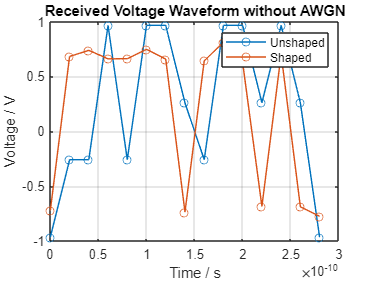

% Scaling factor between output of IQM and output of optical front-end
laserEMag = sqrt(laserPw_Lin/2);
% scaleFactor=1;
scaleFactor = TIA_Gain*eta_ph*laserEMag*laserEMag;

% Cancelling the scaling factor:
voltageQPSK_I = OpticFEOutQPSK_I/scaleFactor; voltageQPSK_Q = OpticFEOutQPSK_Q/scaleFactor; % Unshaped 

% Shaped
if CDcompensate 
    voltageQPSK_shaped_I = OpticFEOutQPSK_shaped_I/scaleFactor;
    voltageQPSK_shaped_Q = OpticFEOutQPSK_shaped_Q/scaleFactor;

elseif ~CDcompensate && (insertAWGN || multipleRotations)
    for i=1:OpticFEOut_3d
        voltageQPSK_shaped_I(:,:,i) = upfirdn(OpticFEOutQPSK_shaped_I(:,:,i)/scaleFactor, filterResponse, 1, 1);
        voltageQPSK_shaped_Q(:,:,i) = upfirdn(OpticFEOutQPSK_shaped_Q(:,:,i)/scaleFactor, filterResponse, 1, 1);
    end
    voltageQPSK_shaped_filtered = voltageQPSK_shaped_I(filterSpan*SpS+1:end-filterSpan*SpS+1,:,:)+1i*voltageQPSK_shaped_Q(filterSpan*SpS+1:end-filterSpan*SpS+1,:,:);

elseif ~CDcompensate
    voltageQPSK_shaped_I = upfirdn(OpticFEOutQPSK_shaped_I/scaleFactor, filterResponse, 1, 1); voltageQPSK_shaped_I = voltageQPSK_shaped_I(filterSpan*SpS+1:end-filterSpan*SpS+1,:,:);
    voltageQPSK_shaped_Q = upfirdn(OpticFEOutQPSK_shaped_Q/scaleFactor, filterResponse, 1, 1); voltageQPSK_shaped_Q = voltageQPSK_shaped_Q(filterSpan*SpS+1:end-filterSpan*SpS+1,:,:);

    voltageQPSK_shaped_filtered = voltageQPSK_shaped_I+1i*voltageQPSK_shaped_Q;
end


plot(t(1:SpS:30), voltageQPSK_I(1:SpS:30,1), "-o");
hold on
plot(t(1:SpS:30), real(voltageQPSK_shaped_filtered(1:SpS:30,1)), "-o");
title("Received Voltage Waveform without AWGN");
xlabel("Time / s")
ylabel("Voltage / V")
legend("Unshaped", "Shaped")
grid on
hold off

### Overlap and Save (CDC)

% Applying the overlap and save method for CD compensation

% CD Compensation
c = 299792458; % Speed of light in m/s
N_CD = ceil(6.67*(D*1e-6)*(CLambda^2)*linkLength*(Rs^2)*SpS/(2*pi*c)) % CD Equalizer Length#

N_CD = 37

N_CD = 50

N_CD = 50

N_FFT = 2^9;

if CDcompensate && (insertAWGN || multipleRotations)
    % Initialising CD compensated vectors
    voltage_CDC = zeros(size(voltageQPSK_I,1),OpticFEOut_3d)
    voltage_shaped_CDC = zeros(size(voltageQPSK_shaped_I,1),OpticFEOut_3d)
    for i=1:OpticFEOut_3d
        voltageQPSK_CDC(:,i) = OverlapSaveCDC(voltageQPSK_I(:,1,i)+1i*voltageQPSK_Q(:,1,i), D, linkLength, CLambda, Rs, 1, SpS, N_FFT, N_CD);
        voltageQPSK_shaped_CDC(:,i) = OverlapSaveCDC(voltageQPSK_shaped_I(:,1,i)+1i*voltageQPSK_shaped_Q(:,1,i), D, linkLength, CLambda, Rs, 1, SpS, N_FFT, N_CD);
    end

    % Filtering chaped signals after CD compensation
    for i=1:OpticFEOut_3d
        voltageQPSK_shaped_filtered(:,i) = upfirdn(real(voltageQPSK_shaped_CDC(:,i)), filterRepsonse, 1, 1)+1i*upfirdn(imag(voltageQPSK_shaped_CDC(:,i)), filterRepsonse, 1, 1);
    end

    % Removing tails
    voltageQPSK_shaped_filtered = voltageQPSK_shaped_filtered(filterSpan*SpS:end-filterSpan*SpS,:);

elseif CDcompensate 
    voltageQPSK_CDC = OverlapSaveCDC(voltageQPSK_I(:,1)+1i*voltageQPSK_Q(:,1), D, linkLength, CLambda, Rs, 1, SpS, N_FFT, N_CD); % Unshaped

    voltageQPSK_shaped_CDC = OverlapSaveCDC(voltageQPSK_shaped_I(:,1)+1i*voltageQPSK_shaped_Q(:,1), D, linkLength, CLambda, Rs, 1, SpS, N_FFT, N_CD); % Shaped
    voltageQPSK_shaped_filtered = upfirdn(real(voltageQPSK_shaped_CDC), filterRepsonse, 1, 1)+1i*upfirdn(imag(voltageQPSK_shaped_CDC), filterRepsonse, 1, 1);
    voltageQPSK_shaped_filtered = voltageQPSK_shaped_filtered(filterSpan*SpS:end-filterSpan*SpS);
end

% New Debugging CD compensation

% Without AWGN
% voltageQPSK_CDC_debug = voltageQPSK_CDC(1:SpS:end); voltageQPSK_CDC_debug(2:2:end) = -conj(voltageQPSK_CDC_debug(2:2:end));
% IntsQPSK_CDC = pskdemod(voltageQPSK_CDC_debug, 4, pi/4);
% BitsQPSK_CDC = int2bit(IntsQPSK_CDC, 2);
% [~, BERQPSK_CDC] = biterr(BitsQPSK_CDC, sourceBitsQPSK)
% 
% voltageQPSK_shaped_CDC_debug = voltageQPSK_shaped_CDC_filtered(1:SpS:end);
% voltageQPSK_shaped_CDC_debug(2:2:end) = -conj(voltageQPSK_shaped_CDC_debug(2:2:end));
% IntsQPSK_shaped_CDC = pskdemod(voltageQPSK_shaped_CDC_debug, 4, pi/4);
% BitsQPSK_shaped_CDC = int2bit(IntsQPSK_shaped_CDC, 2);
% [~, BERQPSK_shaped_CDC] = biterr(BitsQPSK_shaped_CDC, sourceBitsQPSK)
%

% % With AWGN
% BERQPSK_AWGN_CDC = zeros(1,length(SNRb_dB)); BERQPSK_shaped_AWGN_CDC = zeros(1,length(SNRb_dB));
% voltageQPSK_AWGN_CDC_debug = voltageQPSK_AWGN_CDC(1:SpS:end,:); voltageQPSK_AWGN_CDC_debug(2:2:end,:) = -conj(voltageQPSK_AWGN_CDC_debug(2:2:end,:)); 
% 
% voltageQPSK_shaped_AWGN_CDC_debug = voltageQPSK_shaped_AWGN_CDC_filtered(1:SpS:end);
% voltageQPSK_shaped_AWGN_CDC_debug(2:2:end,:) = -conj(voltageQPSK_shaped_AWGN_CDC_debug(2:2:end,:)); 
%     
% for i=1:length(SNRb_dB)
%     IntsQPSK_AWGN_CDC_debug = pskdemod(voltageQPSK_AWGN_CDC_debug(:,i), 4, pi/4);
%     BitsQPSK_AWGN_CDC_debug = int2bit(IntsQPSK_AWGN_CDC_debug, 2);
%     [~, BERQPSK_AWGN_CDC(1,i)] = biterr(BitsQPSK_AWGN_CDC_debug, sourceBitsQPSK);
% 
%     IntsQPSK_shaped_AWGN_CDC_debug = pskdemod(voltageQPSK_shaped_AWGN_CDC_debug(:,i), 4, pi/4);
%     BitsQPSK_shaped_AWGN_CDC_debug = int2bit(IntsQPSK_shaped_AWGN_CDC_debug, 2);
%     [~, BERQPSK_shaped_AWGN_CDC(1,i)] = biterr(BitsQPSK_shaped_AWGN_CDC_debug, sourceBitsQPSK);
% end
% 
% semilogy(SNRb_dB, 0.5*erfc(sqrt(10.^(SNRb_dB/10))));
% hold on
% semilogy(SNRb_dB, BERQPSK_AWGN_CDC, 'o');
% semilogy(SNRb_dB, BERQPSK_shaped_AWGN_CDC, '+');
% title("BER vs. SNR");
% ylabel("BER");
% xlabel("SNR per bit / dB");
% legend("Theoretical", "Unshaped", "Shaped");
% grid on
% hold off

### Adaptive Equalziation

% Without channel distortion
NTaps = 5; NRemove = 280000; N1 = 75000; Mu_T = 1e-5; Mu_DD = Mu_T; Mu_p=2e-2;
% trainSymbsQPSK = codedSymbolsQPSK; % trainSymbsQPSK(2:2:end) = conj(trainSymbsQPSK(2:2:end));
trainSymbsQPSK = sourceSymbolsQPSK;

if multipleRotations || insertAWGN
    for i=1:OpticFEOut_3d
        [equalizedSymbsQPSK(:,i), pQPSK, w11QPSK, w12QPSK, w21QPSK, w22QPSK, errQPSK] = AdapEqualizerAlamouti(voltageQPSK_I(:,1,i)+1i*voltageQPSK_Q(:,1,i), trainSymbsQPSK, SpS, NTaps, Mu_T, Mu_DD, Mu_p, N1, 'QPSK'); % Unshaped
        [equalizedSymbsQPSK_shaped(:,i), pQPSK_shaped, w11QPSK_shaped, w12QPSK_shaped, w21QPSK_shaped, w22QPSK_shaped, errQPSK_shaped] = AdapEqualizerAlamouti(voltageQPSK_shaped_filtered(:,1,i), trainSymbsQPSK, SpS, NTaps, Mu_T, Mu_DD, Mu_p, N1, 'QPSK'); % Shaped
    end
else
    [equalizedSymbsQPSK, pQPSK, w11QPSK, w12QPSK, w21QPSK, w22QPSK, errQPSK] = AdapEqualizerAlamouti(voltageQPSK_I(:,1)+1i*voltageQPSK_Q(:,1), trainSymbsQPSK, SpS, NTaps, Mu_T, Mu_DD, Mu_p, N1, 'QPSK'); % Unshaped
    [equalizedSymbsQPSK_shaped, pQPSK_shaped, w11QPSK_shaped, w12QPSK_shaped, w21QPSK_shaped, w22QPSK_shaped, errQPSK_shaped] = AdapEqualizerAlamouti(voltageQPSK_shaped_filtered(:,1), trainSymbsQPSK, SpS, NTaps, Mu_T, Mu_DD, Mu_p, N1, 'QPSK'); % Shaped
    
end

% Visualising evolution of filter coefficients

% Unshaped

plot([1:size(pQPSK)], w11QPSK', '-');

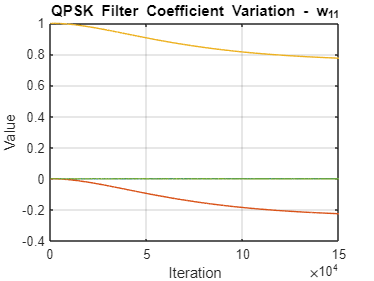

title("QPSK Filter Coefficient Variation - w_{11}")
xlabel("Iteration")
ylabel("Value")
grid on


plot([1:size(pQPSK)], w12QPSK', '-');

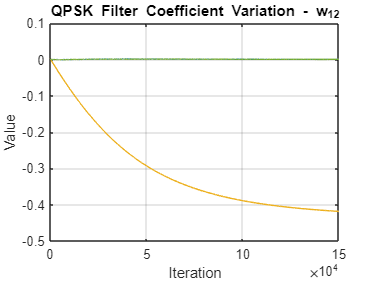

title("QPSK Filter Coefficient Variation - w_{12}")
xlabel("Iteration")
ylabel("Value")
grid on


plot([1:size(pQPSK)], w21QPSK', '-');

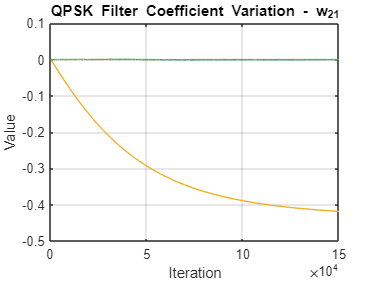

title("QPSK Filter Coefficient Variation - w_{21}")
xlabel("Iteration")
ylabel("Value")
grid on


plot([1:size(pQPSK)], w22QPSK', '-');

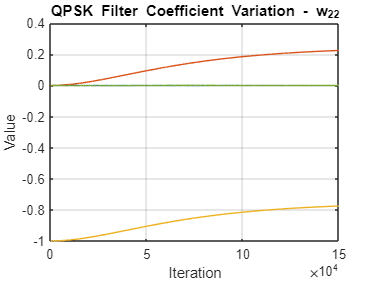

title("QPSK Filter Coefficient Variation - w_{22}")
xlabel("Iteration")
ylabel("Value")
grid on


plot([1:size(pQPSK)], pQPSK, '-');

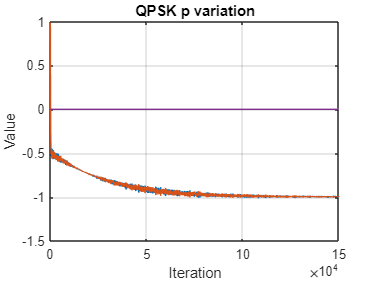

title("QPSK p variation")
xlabel("Iteration")
ylabel("Value")
grid on

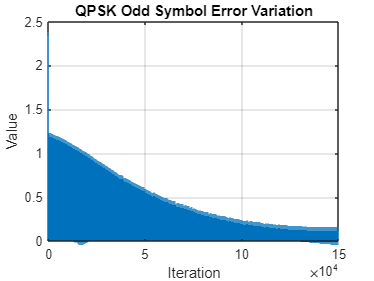


stem([1:size(errQPSK(:,1))], abs(errQPSK(:,1)), '|');
title("QPSK Odd Symbol Error Variation")
xlabel("Iteration")
ylabel("Value")
grid on

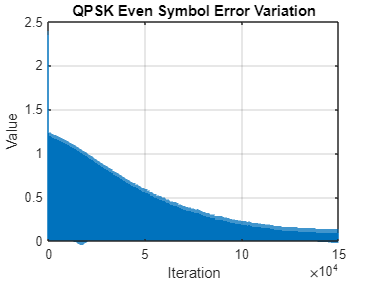


stem([1:size(errQPSK(:,2))], abs(errQPSK(:,2)), '|');
title("QPSK Even Symbol Error Variation")
xlabel("Iteration")
ylabel("Value")
grid on

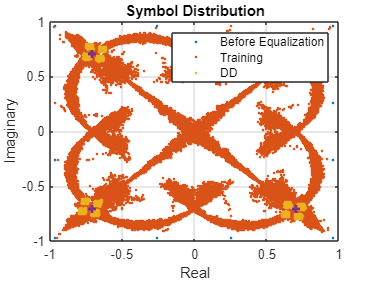


plot(voltageQPSK_I(:,1,1)+1i*voltageQPSK_Q(:,1,1), '.');
hold on
title("Symbol Distribution")
plot(equalizedSymbsQPSK(1:NRemove,1), '.');
plot(equalizedSymbsQPSK(NRemove+1:end,1), '.');
plot(sourceSymbolsQPSK, '+', LineWidth=2);
xlabel("Real")
ylabel("Imaginary")
legend("Before Equalization", "Training", "DD")
grid on
hold off


% -----------------------------------------------------------------------------------------

% Shaped

plot([1:size(pQPSK_shaped)], w11QPSK_shaped', '-');

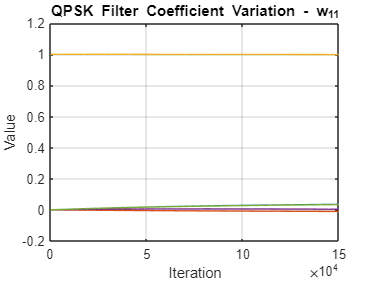

title("QPSK Filter Coefficient Variation - w_{11}")
xlabel("Iteration")
ylabel("Value")
grid on


plot([1:size(pQPSK_shaped)], w12QPSK_shaped', '-');

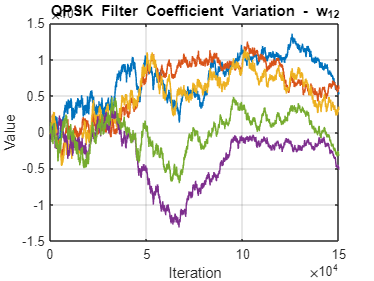

title("QPSK Filter Coefficient Variation - w_{12}")
xlabel("Iteration")
ylabel("Value")
grid on


plot([1:size(pQPSK_shaped)], w21QPSK_shaped', '-');

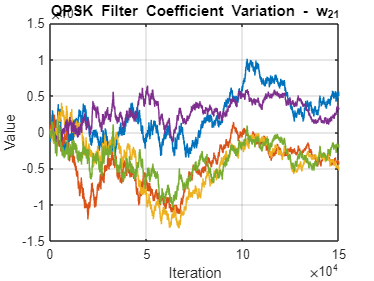

title("QPSK Filter Coefficient Variation - w_{21}")
xlabel("Iteration")
ylabel("Value")
grid on


plot([1:size(pQPSK_shaped)], w22QPSK_shaped', '-');

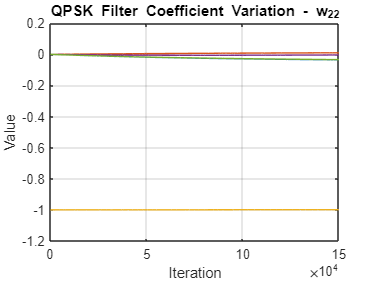

title("QPSK Filter Coefficient Variation - w_{22}")
xlabel("Iteration")
ylabel("Value")
grid on


plot([1:size(pQPSK_shaped)], pQPSK_shaped, '-');

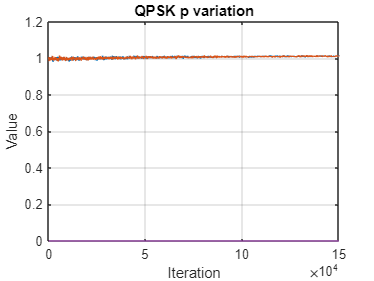

title("QPSK p variation")
xlabel("Iteration")
ylabel("Value")
grid on

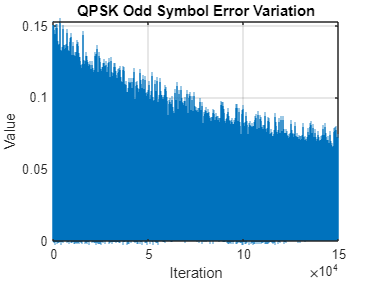


stem([1:size(errQPSK_shaped(:,1))], abs(errQPSK_shaped(:,1)), '|');
title("QPSK Odd Symbol Error Variation")
xlabel("Iteration")
ylabel("Value")
grid on

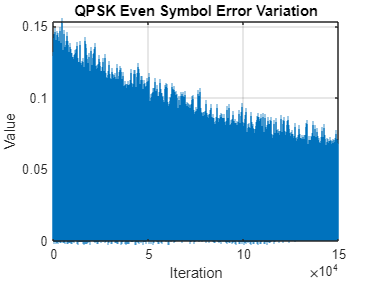


stem([1:size(errQPSK_shaped(:,2))], abs(errQPSK_shaped(:,2)), '|');
title("QPSK Even Symbol Error Variation")
xlabel("Iteration")
ylabel("Value")
grid on

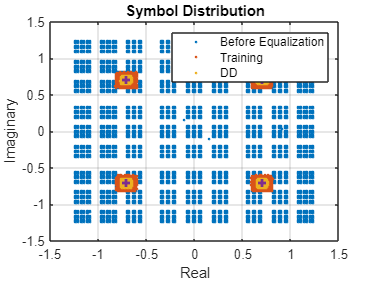


plot(voltageQPSK_shaped_filtered(:,1,1), '.');
hold on
title("Symbol Distribution")
plot(equalizedSymbsQPSK_shaped(1:NRemove,1), '.');
plot(equalizedSymbsQPSK_shaped(NRemove+1:end,1), '.');
plot(sourceSymbolsQPSK, '+', LineWidth=2);
xlabel("Real")
ylabel("Imaginary")
legend("Before Equalization", "Training", "DD")
grid on
hold off

## Receiver

### Decoding and Decision

distortedSymbsQPSK = voltageQPSK_I(1:SpS:end,1,:)+1i*voltageQPSK_Q(1:SpS:end,1,:);
distortedSymbsQPSK(2:2:end,1,:) = -1*conj(distortedSymbsQPSK(2:2:end,1,:)); % Unshaped

distortedSymbsQPSK_shaped = voltageQPSK_shaped_filtered(1:SpS:end,1,:);
distortedSymbsQPSK_shaped(2:2:end,1,:) = -1*conj(distortedSymbsQPSK(2:2:end,1,:)); % Shaped

% Before equalization
IntsQPSK_before = pskdemod(reshape(distortedSymbsQPSK(:,1,:),NSymb,OpticFEOut_3d), 4, pi/4);
BitsQPSK_before = int2bit(IntsQPSK_before, 2);
[~, BERQPSK_before] = biterr(BitsQPSK_before, sourceBitsQPSK) % Unshaped

BERQPSK_before =     0.5000    0.5000    0.5000



IntsQPSK_shaped_before = pskdemod(reshape(distortedSymbsQPSK_shaped(:,1,:),NSymb,OpticFEOut_3d), 4, pi/4);
BitsQPSK_shaped_before = int2bit(IntsQPSK_shaped_before, 2);
[~, BERQPSK_shaped_before] = biterr(BitsQPSK_shaped_before, sourceBitsQPSK) % Shaped

BERQPSK_shaped_before =     0.2505    0.2505    0.2505



% During Training
IntsQPSK_train = pskdemod(equalizedSymbsQPSK(1:N1*2,:), 4, pi/4);
BitsQPSK_train = int2bit(IntsQPSK_train, 2);
[~, BERQPSK_train] = biterr(BitsQPSK_train, sourceBitsQPSK(1:N1*4)) % Unshaped

BERQPSK_train =     0.1097    0.3558    0.1114



IntsQPSK_shaped_train = pskdemod(equalizedSymbsQPSK_shaped(1:N1*2,:), 4, pi/4);
BitsQPSK_shaped_train = int2bit(IntsQPSK_shaped_train, 2);
[~, BERQPSK_shaped_train] = biterr(BitsQPSK_shaped_train, sourceBitsQPSK(1:N1*4)) % Shaped

BERQPSK_shaped_train =      0     0     0



% During Decision-Directed mode
IntsQPSK_dd = pskdemod(equalizedSymbsQPSK(N1*2+1:end,:), 4, pi/4);
BitsQPSK_dd = int2bit(IntsQPSK_dd, 2);
[~, BERQPSK_dd] = biterr(BitsQPSK_dd, sourceBitsQPSK(N1*4+1:end)) % Unshaped

BERQPSK_dd =      0     0     0



IntsQPSK_shaped_dd = pskdemod(equalizedSymbsQPSK_shaped(N1*2+1:end,:), 4, pi/4);
BitsQPSK_shaped_dd = int2bit(IntsQPSK_shaped_dd, 2);
[~, BERQPSK_shaped_dd] = biterr(BitsQPSK_shaped_dd, sourceBitsQPSK(N1*4+1:end)) % Shaped

BERQPSK_shaped_dd =      0     0     0



% Final symbols
IntsQPSK_final = pskdemod(equalizedSymbsQPSK(NRemove+1:end,:), 4, pi/4);
BitsQPSK_final = int2bit(IntsQPSK_final, 2);
[~, BERQPSK_final] = biterr(BitsQPSK_final, sourceBitsQPSK(NRemove*2+1:end)) % Unshaped

BERQPSK_final =      0     0     0



IntsQPSK_shaped_final = pskdemod(equalizedSymbsQPSK_shaped(NRemove+1:end,:), 4, pi/4);
BitsQPSK_shaped_final = int2bit(IntsQPSK_shaped_final, 2);
[~, BERQPSK_shaped_final] = biterr(BitsQPSK_shaped_final, sourceBitsQPSK(NRemove*2+1:end)) % Shaped

BERQPSK_shaped_final =      0     0     0


### BER vs SNR

if insertAWGN 
    semilogy(SNRb_dB, 0.5*erfc(sqrt(10.^(SNRb_dB/10))));
    hold on
    semilogy(SNRb_dB, BERQPSK_final', '*');
    semilogy(SNRb_dB, BERQPSK_shaped_final', 'b+');
    title("BER vs. SNR for QPSK");
    ylabel("BER");
    xlabel("SNR per bit / dB");
    legend("Theoretical", "Simulation-Unshaped", "Simulation-Shaped");
    grid on
    hold off
end